# System 2 : Rössler-Attraktor

Das System von drei gekoppelten Differentialgleichungen lautet:


$$\dot X = - (Y+Z)$$



$$\dot Y = X+aY$$



$$\dot Z = b+(X-c)Z$$


Parameterset 1 : mit a=0,15, b=0,20,c=10,00

Parameterset 2 : mit a=0,20, b=0,20,c=10,00

Wie beeinflussen die einzelnen Parameterden Attraktor?

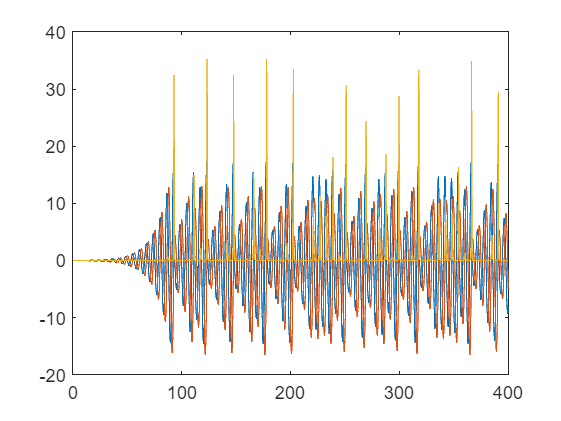

clc
close
clear

%Parameterset 1: a = 0.15;  b = 0.2;  c = 10;
a = 0.15;
b = 0.2;
c = 10;

%Parameterset 1: a = 0.0;  b = 0.15;  c = 8;
% a = 0.2;
% b = 0.15;
% c = 8;

f = @(t,f) [-f(3) - f(2); f(1) + a*f(2) ; (f(1)-c)*f(3) + b];
y0 = [0,0,0];
[t,y] = ode45(f,[0 400],y0);     
plot(t, y)

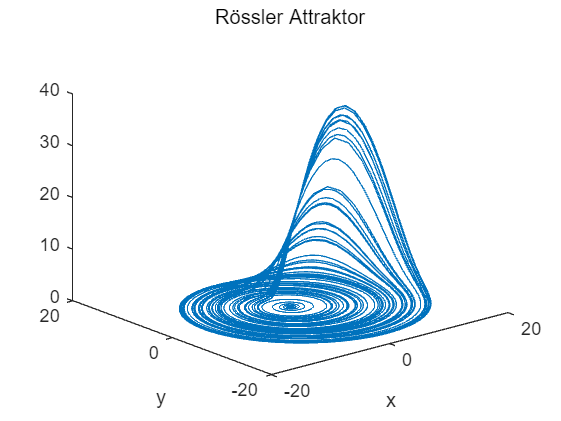

figure
plot3(y(:,1),y(:,2),y(:,3))

title("Rössler Attraktor")
xlabel("x")
ylabel("y")

view([-40 25])